load store\POI30DS1.mat

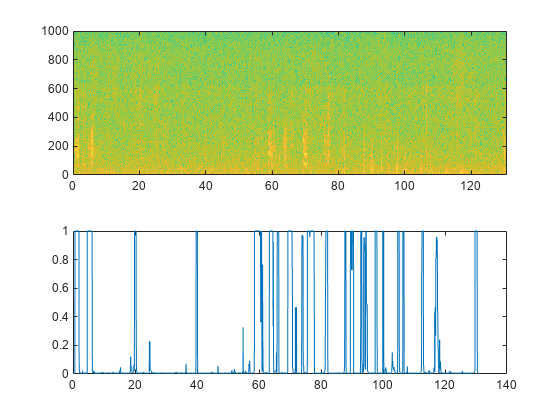

poin = poi(5979);
% poin = poi(597);
[x, S, f, t] = POI.plotPOI(poin);

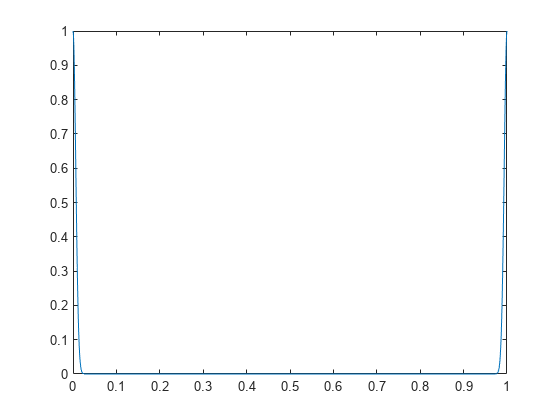

sf = waveletScattering("Boundary","reflection","InvarianceScale",128, "SamplingFrequency", 1, "SignalLength", numel(x), "QualityFactors", [8 2]);
fc = centerFrequencies(sf);
[filters,ffilt] = filterbank(sf);
figure
plot(ffilt,filters{1}.phift)

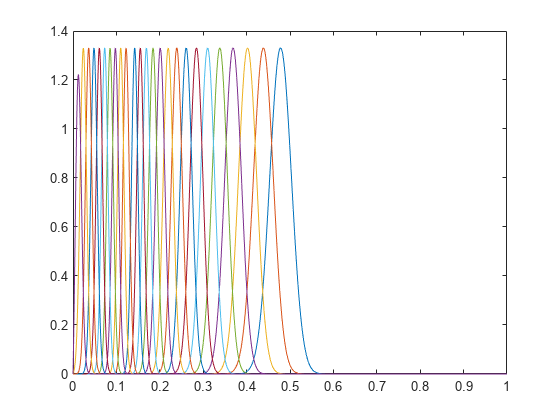

plot(ffilt,filters{2}.psift)

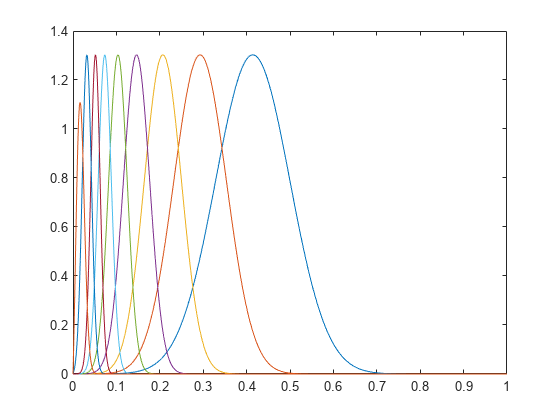

plot(ffilt,filters{3}.psift)

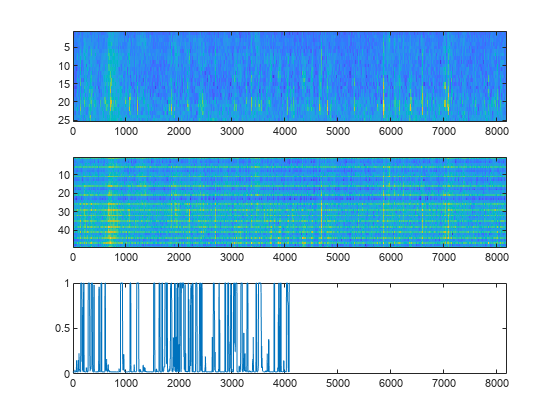

[s,u] = scatteringTransform(sf, x);
s1 = cell2mat((s{2}.signals)')';
s2 = cell2mat((s{3}.signals)')';
% s3 = cell2mat((s{4}.signals)')';
figure
ax1 = subplot(311);
Tools.plotTF(s1.^2, 1:size(s1, 1), false, true);
set(gca, 'Ydir', 'reverse')
ax2 = subplot(312);
linkaxes([ax1 ax2], 'x')
Tools.plotTF(s2, 1:size(s2, 1), false, true);
set(gca, 'Ydir', 'reverse')
ax2 = subplot(313);
plot(poin.SignalProbability(1:end));
linkaxes([ax1 ax2], 'x')

figure



sf = waveletScattering("Boundary","reflection","InvarianceScale",256/POI.fs, "SamplingFrequency", POI.fs, "SignalLength", numel(x), "QualityFactors", [32], "OptimizePath",true, "Precision","single");
fc = centerFrequencies(sf);
[filters,ffilt] = filterbank(sf);


tic
[s,u] = scatteringTransform(sf, x);
toc

Elapsed time is 0.530200 seconds.


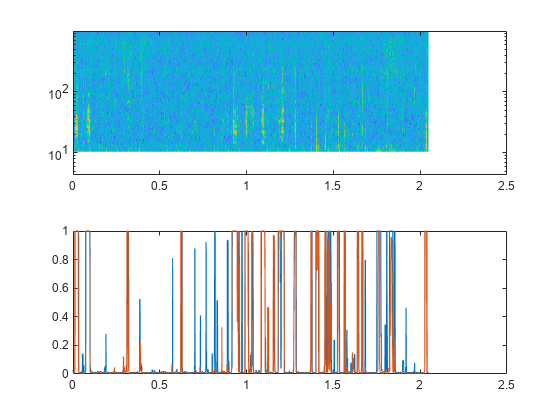



s1 = cell2mat((s{2}.signals)')';
s1med = POI.NoiseEstimate(s1);
s1 = s1./s1med;
s1 = s1.^2;
[H, probs, mu_ns, mu_s, sigma_ns, sigma_s, comp_ns, comp_s, converged, n_iter, LL, mon, fmin, fmax, Ht, contam] = SignalDetection.softSignalDetectionGMM(s1, POI.M);

figure
t = (0:size(s1,2)-1)/POI.fs;
ax1 = subplot(211);
Tools.plotTF(s1, fc, true, true ,t);
ax2 = subplot(212);
plot(t, probs)
hold on
plot(t(1:4089), poin.SignalProbability)
linkaxes([ax1, ax2], 'x')